% AE6511 Hw5 Problem 3 MATLAB code
% Tomoki Koike
clear all; close all; clc;  % housekeeping commands
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

alpha = 0.2;  % global constant for the alpha term
% BVP solution
t_f = 1; % intial guess of final time 
tspan = linspace(0, t_f, 2000);
init_guess = [1, 1, 1, 1, t_f]';
method = 1;

switch method 
    case 1  % bvp4c
        solinit = bvpinit(linspace(0, 1, 4), init_guess);
        opts = bvpset('RelTol',1e-5, 'AbsTol',1e-6,'Stats','on','Nmax',500);
        sol = bvp4c(@bvp_ode, @bvp_bc, solinit, opts, alpha);
        
        % Unpack results
        T = linspace(0,1,1000);
        [xopt,xdopt] = deval(sol,T);
        xopt = xopt.'; xdopt = xdopt.';
        tf_eval = mean(xopt(1,5));
        tf_out = abs(tf_eval);
        tspan = tf_out * T;
        x_sol = xopt(:,1);
        y_sol = xopt(:,2);
        lambda1_sol = xopt(:,3);
        lambda2_sol = xopt(:,4);
        theta_sol = atan2(lambda2_sol,lambda1_sol);
        H = (-1 + lambda1_sol .* xdopt(:,1)./tf_eval ...
            + lambda2_sol .* xdopt(:,2)/tf_eval);
        
    case 2  % ode45
        optslv = optimset('TolX',1e-7,'TolFun',1e-7, ...
            'Display','off','MaxIter',500);
        xout = ode45(@(t, y) bvp_ode(t, y, alpha), ...
            [0, t_f], init_guess, optslv);
        sol = xout.y'; T = xout.x;
        % Hamiltonian
        xsol = interp1(T,sol(:,1),tspan); ysol = interp1(T,sol(:,2),tspan); 
        thetasol = interp1(T,sol(:,3),tspan);
        lambda1 = interp1(T,sol(:,4),tspan); lambda2 = interp1(T,sol(:,5),tspan); 
        u = -alpha * (3*ysol - ysol.^3);
        H = 1 + lambda1 .* (cos(thetasol) + u) + lambda2 .* sin(thetasol);
end

The solution was obtained on a mesh of 19 points.
The maximum residual is  6.171e-06. 
There were 576 calls to the ODE function. 
There were 112 calls to the BC function. 


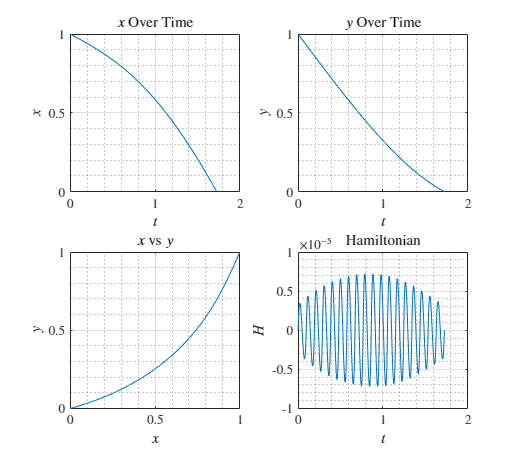

% Plotting the results 

fig = figure("Renderer","painters","Position",[60 60 900 800]);
    % x vs t
    subplot(2,2,1)
    plot(tspan, x_sol)
    title('$x$ Over Time')
    xlabel('$t$')
    ylabel('$x$')
    grid on; grid minor; box on;
    % y vs t
    subplot(2,2,2)
    plot(tspan, y_sol)
    title('$y$ Over Time')
    xlabel('$t$')
    ylabel('$y$')
    grid on; grid minor; box on;
    % x - y 
    subplot(2,2,3)
    plot(x_sol, y_sol)
    title('$x$ vs $y$')
    xlabel('$x$')
    ylabel('$y$')
    grid on; grid minor; box on;
    % Hamiltonian 
    subplot(2,2,4)
    plot(tspan, H)
    title('Hamiltonian')
    xlabel('$t$')
    ylabel('$H$')
    grid on; grid minor; box on;
saveas(fig,'p3.png');

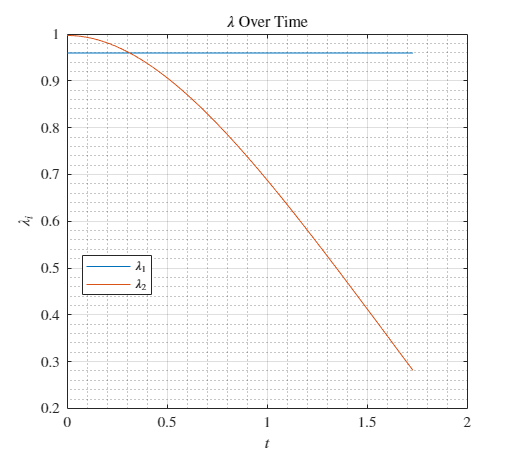

% Plot costates 
fig = figure("Renderer","painters","Position",[60 60 900 800]);
    plot(tspan, lambda1_sol,'DisplayName','$\lambda_1$')
    hold on;
    plot(tspan, lambda2_sol,'DisplayName','$\lambda_2$')
    title('$\lambda$ Over Time')
    xlabel('$t$')
    ylabel('$\lambda_i$')
    legend('Location','best'); grid on; grid minor; box on; hold off;
saveas(fig,'p3_lambda.png');

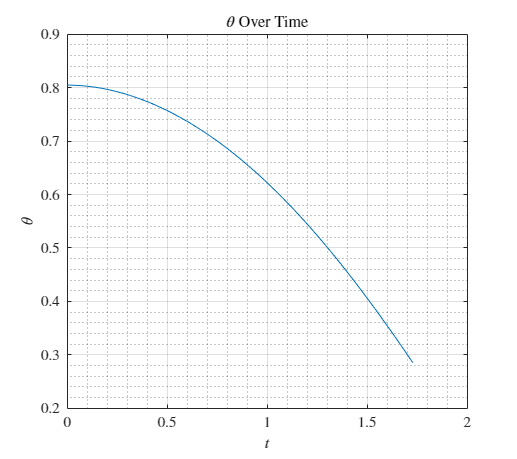

% Plot control 
fig = figure("Renderer","painters","Position",[60 60 900 800]);
    plot(tspan, theta_sol)
    title('$\theta$ Over Time')
    xlabel('$t$')
    ylabel('$\theta$')
    grid on; grid minor; box on;
saveas(fig,'p3_theta.png');

## Functions

function dydt = bvp_ode(t, y, alpha)
%{
    Function: bvp_ode
    ------------------
    ODE representation of the optimal control problem to be solved by bvp.

    args: 
        t: time 
        y: state variables        
        alpha: constant (known parameter)
    returns:
        derivative of the state variables 
%}

    u = -alpha * (3 * y(2) - y(2)^3);
    theta = atan2(y(4),y(3));
    dydt(1) = cos(theta) + u;
    dydt(2) = sin(theta);
    dydt(3) = 0;
    dydt(4) = 3 * alpha * y(3) - 3 * alpha * y(3) * y(2)^2;
    dydt(5) = 0;
    dydt = dydt' * y(5);
end

function res = bvp_bc(ya, yb, alpha)
%{
    Function: bvp_bc
    -----------------
    Boundary conditions for the optimal control problem solved by bvp.
    
    args: 
        ya: lower boundary conditions
        yb: upper boundary conditions
        alpha: constant (known parameter)
    returns:
        matrix containing all the boundary conditions
%}
    theta_f = atan2(yb(4),yb(3));
    u_f = -alpha*(3*yb(2) - yb(2)^3);
    res(1) = ya(1) - 1;
    res(2) = ya(2) - 1;
    res(3) = yb(1);
    res(4) = yb(2);
    res(5) = ((yb(3)*(cos(theta_f)+u_f) ...
        +yb(4)*sin(theta_f) - 1)*yb(5));
    res = res';
end